# Workflow

`----------------------------------------------------------------------------------------------------------------------------------------`

`NOTE:`

`Examples of compiled files are stored under the folder "\redistribution".`

`When you run the code above, please make sure the current folder is the root directory.`

`----------------------------------------------------------------------------------------------------------------------------------------`

Add necessary file folders to path:

addpath("scripts");
addpath("model");
addpath("data");
addpath("liveScripts");
% addpath("redistribution");  % DO NOT uncomment this line of code!!!

## Create the plant model using Simulink/Simscape

open_system('model\spe_servomotor.slx')

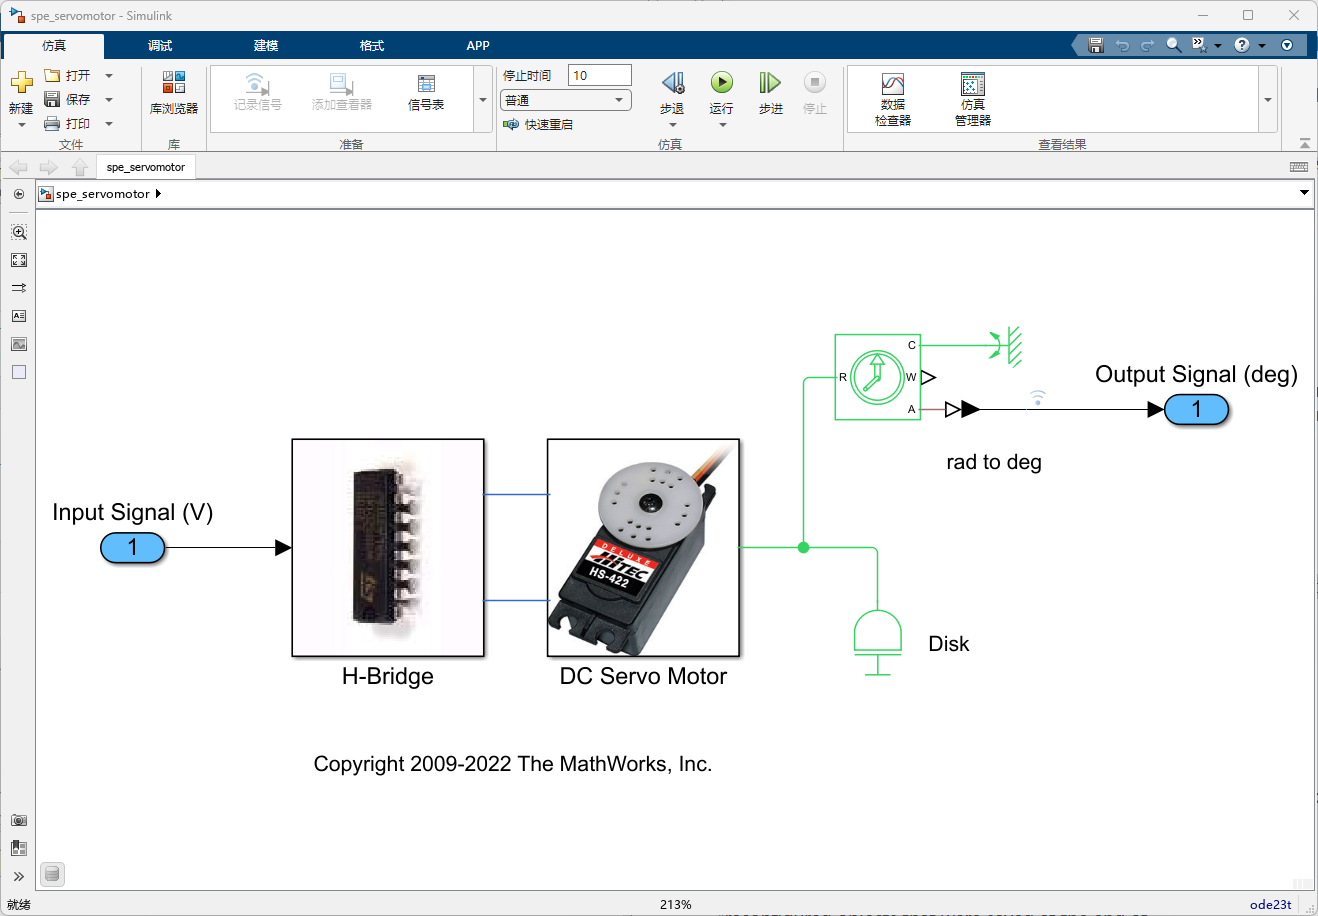

## Estimate plant parameters using Parameter Estimator App

(using Simulink Design Optimization Toolbox)

load spe_servomotor_spesession
spetool(SDOSessionData)

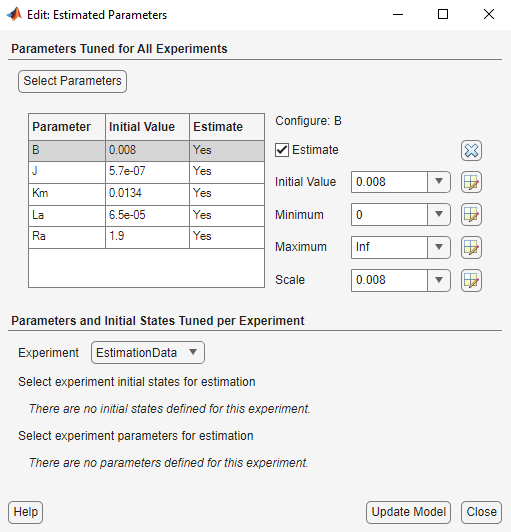

Before deployment, the parameters to be estimated must be configured as "Run-time" （运行时）instead of "Compile-time"（编译时）。

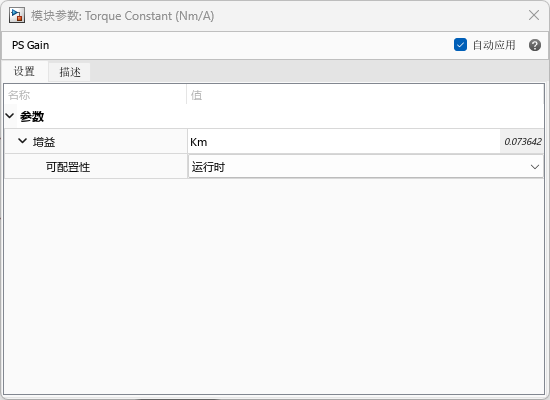

## Generate functions for Deployment directly from the Parameter Estimator App

Navigate to the **Estimate** button in the toolstrip and from the dropdown list, select **Generate Function for Deployment**.

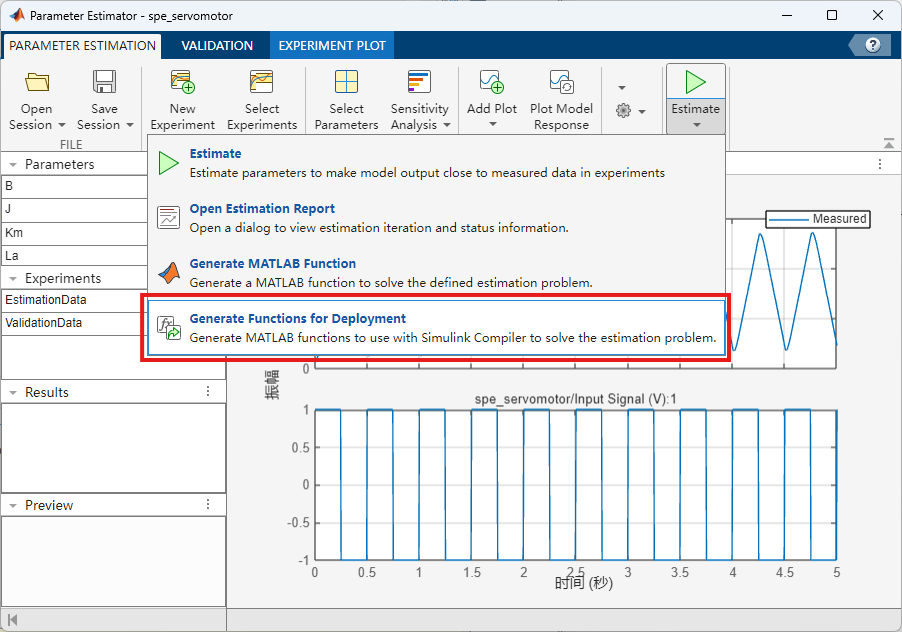

`----------------------------------------------------------------------------------------------------------------------------------------`

`NOTE: The Setup-File and Run-File under folder \scripts are modified, save an copy before you replace them with new generated functions.`

`----------------------------------------------------------------------------------------------------------------------------------------`

### **Setup-File for Deployed Parameter Estimation**

To estimate parameters in deployed mode, the code for non-deployed parameter estimation can be split into a *setup* file to use in non-deployed mode, and a *run* file to use in deployed mode. The setup file is available as `parameterEstimation_spe_servomotor_setup.m` and the main parts are:

- Define parameters

- Define experiments

- Prepare for deployment and save

edit parameterEstimation_spe_servomotor_setup.m

#### Modification of the Setup-File

Edit the setup file if necessary, for example, assume the test point information is stored in a MAT file named as testpointDatabase.mat:

testpointDatabase = {'eq1','eq2','eq3','eq4','eq5','eq6'};
save testpointDatabase.mat testpointDatabase

we can load the file and use the IDs to name each equipment in the fleet, and save a seperate MAT file to store the configured object for deployment:

Run the script after necessary modification:

parameterEstimation_spe_servomotor_setup()

### **Run-File for Deployed Parameter Estimation**

The *run* file is available as `parameterEstimation_spe_servomotor_run.m` and the main parts are:

- Load preconfigured deployment objects

- Update experiments and parameters

- Run optimization

- Update Parameter Database

Open and Edit the generated Run-File:

edit parameterEstimation_spe_servomotor_run.m

#### Modification of the Run-File 

Part 1: load seperate MAT file 

Part 2: save as seperate MAT file

When ready, use the `mcc` command to compile the `parameterEstimation_spe_servomotor_run.m` function from either the MATLAB command window or the DOS or UNIX® command prompt. You need to have MATLAB Runtime installed to complete the following steps. 

mcc -m parameterEstimation_spe_servomotor_run

## Batch Estimation using parallel for-loop 

(using Parallel Computing Toolbox)

edit batchEstimation.m

## Compile the batchEstimation.m file as a standalone exe file

(using Simulink Compiler + MATLAB Compiler)

mcc -m batchEstimation

## Run the exe file in Command

% function batchEstimation(dataFilePath)

The exe file requires an input argument, i.e. data file path, which is the data folder with csv files.

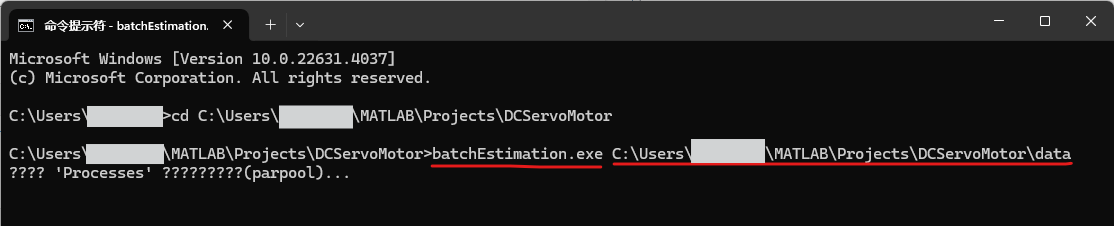

## Wrap up

% Close the model
bdclose('spe_servomotor')

## Appendix